# Multistep methods for solving the Cauchy problem for the ODE

## Taks 1

**Явний метод на 3-х точках:**

    інтерполяційний поліном - $F(t) = f(t_{n-1}) + (t - t_{n-1})[(t - t_{n-2})f(t_{n-3}) - (t - t_{n-3})f(t_{n-2})] / ((t_{n-1} - t_{n-2})(t_{n-1} - t_{n-3}))$

    розрахункова формула - $y_{n} = y_{n-1} + h/12 * (23f(x_{n-1}, y_{n-1}) - 16f(x_{n-2}, y_{n-2}) + 5f(x_{n-3}, y_{n-3}))$

    похибка - $O(h^3)$

**Неявний метод на 3-х точках:**

    інтерполяційний поліном - $F(t) = f(t_n) + (t - t_{n})[(t - t_{n-1})f(t_{n-2}) - (t - t_{n-2})f(t_{n-1})] / ((t_n - t_{n-1})(t_n - t_{n-2}))$

    розрахункова формула - $y_{n} = y_{n-1} + h/12 * (5f(x_{n}, y_{n}) + 8f(x_{n-1}, y_{n-1}) - f(x_{n-2}, y_{n-2}))$

    похибка - $O(h^3)$

## Taks 2

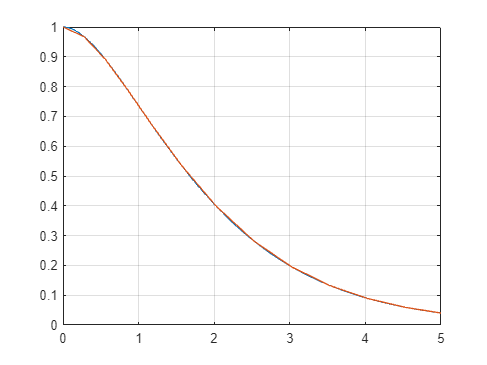

x0 = 0; xn = 5; h = 0.01; y0 = 1;
dfunc = @(x, u)(exp(-x) - u);

fig = figure;

[X, Y] = explicitAdamsMethod(dfunc, x0, xn, y0, h);
plot(X, Y);

hold on;

[X, Y] = ode23(dfunc, [x0, xn], 1);
plot(X, Y);

grid on;
hold off;

## Taks 3

% 11q^3 - 18q^2 + 9q - 2 - характеристичне рівняння

## 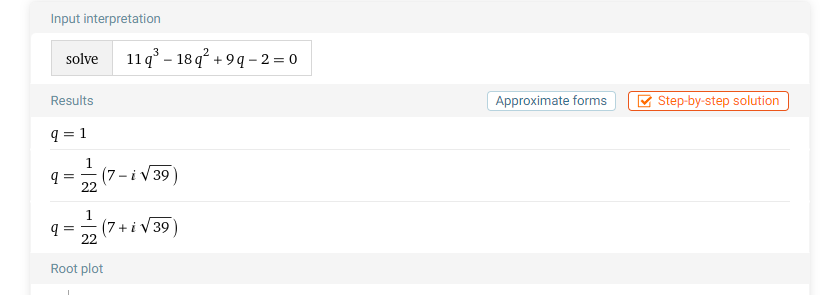

тож умова коренів $|q_i| \leq 1$-не виконується (беремо по 1 кругу комлексної площини. Самрський, Чисельні методи, ст.240)

## Taks 4

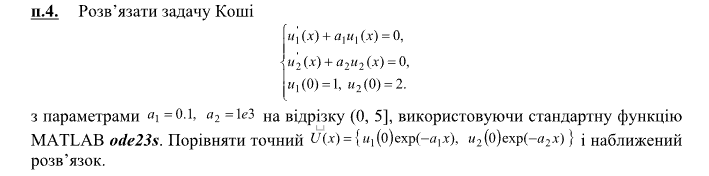

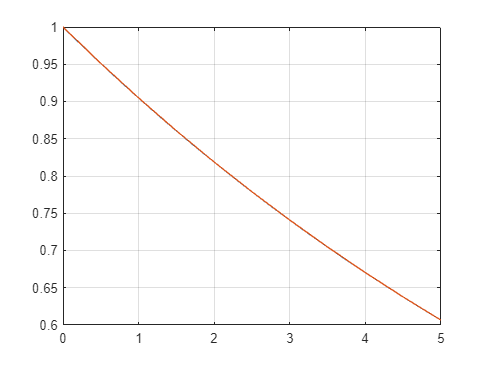

a1 = 0.1; a2 = 10^(-3);
x0 = 0; xn = 5; y01 = 1; y02 = 2;

dfunc = @(x, u)([-a1*u(1); -a2*u(2)]);

[X1, Y1] = explicitAdamsMethod2Dim(dfunc, x0, xn, [y01; y02], h);
[X2, Y2] = ode23s(dfunc, [x0, xn], [y01; y02]);

plot(X1, Y1(1,:));
hold on;
plot(X2, Y2(:,1));
grid on;
hold off;

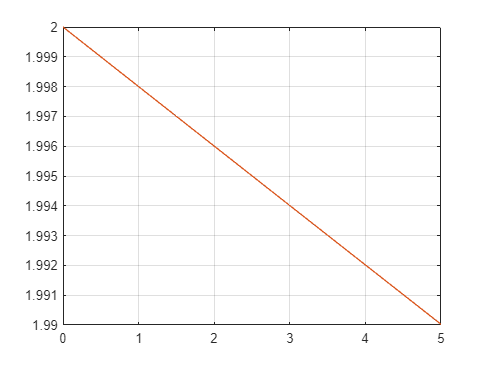


plot(X1, Y1(2,:));
hold on;
plot(X2, Y2(:,2));
grid on;
hold off;

export("Computational methods/Lab4.mlx")

ans = 'E:\Work\Applied math\Matlab\Lab4.pdf'

function [X, Y] = explicitAdamsMethod(func, x0, xn, y0, h)
    X = x0:h:xn;
    Y = zeros(length(X), 1);
    Y(1) = y0;

    k1 = h*func(X(1), Y(1));
    k2 = h*func(X(1) + h/2, Y(1) + k1/2);
    k3 = h*func(X(1) + h/2, Y(1) + k2/2);
    k4 = h*func(X(1), Y(1) + k3);
    Y(2) = Y(1) + (k1 + 2*k2 + 2*k3 + k4)/6;

    for i = 2:length(X)-1
        Y(i + 1) = Y(i) + h/2 * (3*func(X(i), Y(i)) - func(X(i - 1), Y(i - 1)));
    end
end

function [X, Y] = explicitAdamsMethod2Dim(func, x0, xn, y0, h)
    X = x0:h:xn;
    Y = zeros(2, length(X));
    Y(:,1) = y0;

    k1 = h*func(X(1), Y(:,1));
    k2 = h*func(X(1) + h/2, Y(:,1) + k1/2);
    k3 = h*func(X(1) + h/2, Y(:,1) + k2/2);
    k4 = h*func(X(1), Y(:,1) + k3);
    Y(:,2) = Y(:,1) + (k1 + 2*k2 + 2*k3 + k4)/6;

    for i = 2:length(X)-1
        Y(:,i+1) = Y(:,i) + h/2 * (3*func(X(i), Y(:,i)) - func(X(i - 1), Y(:,i-1)));
    end
end